# NAU Ground Thermal Conductivity & Heat Pump Analysis

#### by Ethan Shoemaker

clear
clc
close all

#### Import Raw Data

warning('off')
Data512 = readtable('AZ_Flagstaff_512ft.txt','PreserveVariableNames',true);
Data848 = readtable('AZ_Flagstaff_848ft.txt','PreserveVariableNames',true);

%Ignore the warnings about the datetime data.  You can view the dates directly
%by observing the tables from the workspace. Time is already converted to
%hours in column 2, and this is the only temporal data you need for most of
%the analysis.


#### Converting table data into Matlab Vectors

1)  Preparing 512 ft. Borehole data

t_512 = table2array((Data512(:,2))); %creates a time column vector for the 512' borehole experiment,hours
Ts_512 = table2array((Data512(:,3))); %creates a supply temperature column vector for the 512' borehole experiment, degrees F
Tr_512 = table2array((Data512(:,4))); %creates a return temperature column vector for the 512' borehole, degrees F
I_512 = table2array((Data512(:,5)));  %creates a current column vector for the 512' borehole, amps
V_512 = table2array((Data512(:,6))); %creates a voltage column vector for the 512' borehole, volts


%Isolating data after the first 10 hours%

i = 1; %Creates an iterative index

while t_512(i) < 10   %While loops finds the last index before t = 10 hours
    i = i+1;
    start512 = i;
end
index512 = start512 + 1; %Identifies index to start evaluating 512; data, @ t = 10 hours 

%Modifies column vectors to only t > 10 hour data points.
t_512 = t_512(index512:end);
Ts_512 = Ts_512(index512:end);
Tr_512 = Tr_512(index512:end); 
I_512 = I_512(index512:end);  
V_512 = V_512(index512:end);


N_512 = length(t_512); %Finds number of measurements after 10 hours


2) Preparing 848 ft. Borehole Data [ STUDENT COMPLETES]

t_848 = table2array((Data848(:,2))); %creates a time column vector for the 512' borehole experiment,hours
Ts_848 = table2array((Data848(:,3))); %creates a supply temperature column vector for the 512' borehole experiment, degrees F
Tr_848 = table2array((Data848(:,4))); %creates a return temperature column vector for the 512' borehole, degrees F
I_848 = table2array((Data848(:,5)));  %creates a current column vector for the 512' borehole, amps
V_848 = table2array((Data848(:,6))); %creates a voltage column vector for the 512' borehole, volts


%Isolating data after the first 10 hours%

i = 1; %Creates an iterative index

while t_848(i) < 10   %While loops finds the last index before t = 10 hours
    i = i+1;
    start848 = i;
end
index848 = start848 + 1; %Identifies index to start evaluating 512; data, @ t = 10 hours 

%Modifies column vectors to only t > 10 hour data points.
t_848 = t_848(index848:end);
Ts_848 = Ts_848(index848:end);
Tr_848 = Tr_848(index848:end); 
I_848 = I_848(index848:end);  
V_848 = V_848(index848:end);


N_848 = length(t_848); %Finds number of measurements after 10 hours

P_512 = I_512.*V_512;
P_848 = I_848.*V_848;

#### Q1 Checking on Test Requirements:  

Requirement: Minimum test duration of 36 hours

if max(t_512)>36 && max(t_848)>36
    fprintf('Requirement is met, test\n duration of 512 ft hole is %.2f\n hours, and test duration of 848\n ft hole is %.2f hours',max(t_512),max(t_848))
else
    disp('Requirement is not met')
end

Requirement is met, test
 duration of 512 ft hole is 44.01
 hours, and test duration of 848
 ft hole is 43.87 hours

Requirement: The standard deviation of the power should be less than or equal to 1.5% of the average power, with maximum power variation of less than or equal to 10% of the average power.

avgP_512 = mean(P_512);
avgP_848 = mean(P_848);
stdP_512 = std(P_512);
stdP_848 = std(P_848);
rangeP_512 = range(P_512);
rangeP_848 = range(P_848);

if stdP_848 <= 0.015*avgP_848 && rangeP_848 <= 0.1*avgP_848 && stdP_512 <= 0.015*avgP_512 && rangeP_512 <= 0.1*avgP_512
    fprintf('Requirement is satisfied. \nStandard deviation of power is \n%.2f percent of average power for 848 foot \nbore hole and %.2f percent of average power \nfor 512 foot hole. \nMaximum power variation is %.2f \npercent of average power for 848 foot \nbore hole and %.2f percent of average power \nfor 512 foot bore hole.',(stdP_848/avgP_848)*100,(rangeP_848/avgP_848)*100,(stdP_512/avgP_512)*100,(rangeP_512/avgP_512)*100)
else
    disp('Requirement is not met')
end

Requirement is satisfied. 
Standard deviation of power is 
0.13 percent of average power for 848 foot 
bore hole and 0.49 percent of average power 
for 512 foot hole. 
Maximum power variation is 0.14 
percent of average power for 848 foot 
bore hole and 0.53 percent of average power 
for 512 foot bore hole.

Requirement: The heat flux rate should be 51 Btu/hr (15 W) to 85 Btu/hr (25 W) per foot of installed bore depth to best simulate the expected peak loads on the u-bend.

if avgP_848>15*848 && avgP_848<25*848 && avgP_512>15*512 && avgP_512<25*512
    fprintf('Requirement is satisfied. \nHeat Flux Rate is %.2f Btu/hr\n(%.2f W) and %.2f Btu/hr\n(%.2f W) per foot of bore depth for \nthe 848 foot bore and 512 foot bore \nrespectively.', (avgP_848/848)*3.41, avgP_848/848,(avgP_512/512)*3.41, avgP_512/512)
else
    disp('Requirement is not satisfied')
end

Requirement is satisfied. 
Heat Flux Rate is 56.91 Btu/hr
(16.69 W) and 62.96 Btu/hr
(18.46 W) per foot of bore depth for 
the 848 foot bore and 512 foot bore 
respectively.

Requirement: Flow rates should be sufficient to provide a differential loop temperature of 6 to 12°F.

if max(abs(Ts_512-Tr_512))<12 && min(abs(Ts_512-Tr_512))>6 && max(abs(Ts_848-Tr_848))<12 && min(abs(Ts_848-Tr_848))>6
    fprintf('Requirement is satisfied. Max temperature difference is %.2f for 512 foot bore and %.2f for 848 foot bore. Minimum temperature difference is %.2f for 512 foot bore and %.2f for 848 foot bore.',max(abs(Ts_512-Tr_512)),max(abs(Ts_848-Tr_848)),min(abs(Ts_512-Tr_512)),min(abs(Ts_848-Tr_848)))
else
    fprintf('Requirement is not satisfied. Max \ntemperature difference is %.2f \nfor 512 foot bore and %.2f for 848 \nfoot bore. Minimum temperature \ndifference is %.2f for 512 foot \nre and %.2f for 848 foot bore.',max(abs(Ts_512-Tr_512)),max(abs(Ts_848-Tr_848)),min(abs(Ts_512-Tr_512)),min(abs(Ts_848-Tr_848)))
end

Requirement is not satisfied. Max 
temperature difference is 4.88 
for 512 foot bore and 7.00 for 848 
foot bore. Minimum temperature 
difference is 4.02 for 512 foot 
re and 5.82 for 848 foot bore.

#### Q2 Water Heat Rate and Heating Power Quality

P_512L = (P_512/512)*3.41; %length normalized heat rate in Btu/hr*ft. 3.41 is W to Btu/hr conversion factor.
P_848L = (P_848/848)*3.41; %length normalized heat rate in Btu/hr*ft. 3.41 is W to Btu/hr conversion factor.
avgP_512L = mean(P_512L) %average length normalized heat rate in Btu/hr for 512 foot bore

avgP_512L = 62.9593

avgP_848L = mean(P_848L) %average length normalized heat rate in Btu/hr for 848 foot bore

avgP_848L = 56.9150


stdP_512L = std(P_512L); %sample standard deviation of length normalized heat rate for 512 foot bore
stdP_848L = std(P_848L); %sample standard deviation of length normalized heat rate for 848 foot bore

stdmean512L = stdP_512L/sqrt(numel(P_512L)) %standard deviation of the mean of length normalized heat rate for 512 foot bore

stdmean512L = 0.0044

studentst512L = tinv([0.025 0.975],numel(P_512L)) %students t value

studentst512L =    -1.9658    1.9658



%CI of average length normalized heat rate in Btu/hr for 512 foot bore hole
CI_avgP512L = studentst512L*stdmean512L;
CI_avgP512L = CI_avgP512L(2)

CI_avgP512L = 0.0086


%Relative minimum, relative maximum, and relative accuracy
%of average length normalized heat rate (Btu/hr)
RelativeMin512 = (min(P_512L)/avgP_512L)*100

RelativeMin512 = 99.7370

RelativeMax512 = (max(P_512L)/avgP_512L)*100

RelativeMax512 = 100.2679

RelAcc_avgP512L = (CI_avgP512L/avgP_512L)*100

RelAcc_avgP512L = 0.0137


stdmean848L = stdP_848L/sqrt(numel(P_848L)) %standard deviation of the mean of length normalized heat rate for 848 foot bore

stdmean848L = 0.0038

studentst848L = tinv([0.025 0.975],numel(P_848L)); %students t value

%CI of average length normalized heat rate in Btu/hr for 848 foot bore hole
CI_avgP848L = studentst848L*stdmean848L;
CI_avgP848L = CI_avgP848L(2)

CI_avgP848L = 0.0075


%Relative minimum, relative maximum, and relative accuracy
%of average length normalized heat rate (Btu/hr)
RelativeMin848 = (min(P_848L)/avgP_848L)*100

RelativeMin848 = 99.6924

RelativeMax848 = (max(P_848L)/avgP_848L)*100

RelativeMax848 = 100.1796

RelAcc_avgP848L = (CI_avgP848L/avgP_848L)*100

RelAcc_avgP848L = 0.0131

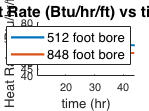


figure(1);  %Creates distinct figures in the matlab script
hold on
plot(t_512,P_512L,'LineWidth',2.0)  %Here you need to indicate what should be plotted
xlabel('time (hr)','FontSize',12); %Axis labels
ylabel('Heat Rate (Btu/hr/ft)','FontSize',12);
plot(t_848,P_848L,'LineWidth',2.0)  %Here you need to indicate what should be plotted
ylim([40 80]); %sets y-axis range
yticks([40:5:80]);
title('Heat Rate (Btu/hr/ft) vs time (hr)','FontSize',14)
legend('512 foot bore','848 foot bore','location','Northeast','FontSize',12) %Fill in legend labels
hold off

#### Q3 Water Temperature

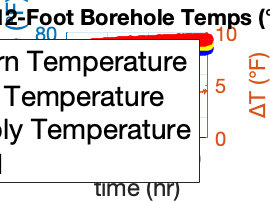

Tf_512 = (Tr_512 + Ts_512)./2; %average of return and supply temp for 512 foot bore hole(F)
Tf_848 = (Tr_848 + Ts_848)./2; %average of return and supply temp for 848 foot bore hole(F)
deltaT_512 = abs(Tr_512 - Ts_512); %change in temperature from supply to return (512 foot bore - F)
deltaT_848 = abs(Tr_848 - Ts_848); %change in temperature from supply to return (848 foot bore - F)

figure(2);
hold on
yyaxis left %Plot the return, supply and averge fluid temperature of 512' borehole
xlabel('time (hr)','FontSize',12); %Axis labels
ylabel('Temperature (°F)', 'FontSize',12)
scatter(t_512, Tr_512,'b')
scatter(t_512, Tf_512,'yellow')
scatter(t_512, Ts_512,'red')
ylim([30 80])
legend('Return Temperature','Fluid Temperature','Supply Temperature','ΔT','location','southeast','FontSize',14) 
yyaxis right  %Plot the delta T
plot(t_512,deltaT_512)
ylabel('ΔT (°F)')
ylim([0 10])
title('512-Foot Borehole Temps (°F)')
hold off
grid
fpos = get(gcf,'Position');
set(gcf, 'Position',fpos+[700 -700 0 0]) %Avoids an overlap of the figures

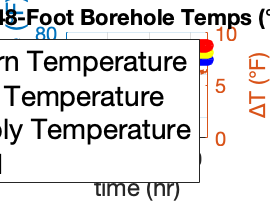


figure(3);
hold on
yyaxis left %Plot the return, supply and averge fluid temperature of 512' borehole
xlabel('time (hr)','FontSize',12); %Axis labels
ylabel('Temperature (°F)', 'FontSize',12)
scatter(t_848, Tr_848,'b')
scatter(t_848, Tf_848,'yellow')
scatter(t_848, Ts_848,'red')
ylim([30 80])
legend('Return Temperature','Fluid Temperature','Supply Temperature','ΔT','location','southeast','FontSize',14) 
yyaxis right  %Plot the delta T
plot(t_848,deltaT_848)
ylabel('ΔT (°F)')
ylim([0 10])
title('848-Foot Borehole Temps (°F)')
hold off
grid
fpos = get(gcf,'Position');
set(gcf, 'Position',fpos+[700 -700 0 0]) %Avoids an overlap of the figures

#### Q4 Temp vs. ln(time)

To_512 = 49.4; %undisturbed ground temperature (512 foot bore hole)
To_848 = 49.7; %undisturbed ground temperature (848 foot bore hole)
TfTo_512 = Tf_512 - To_512; %fluid temp - undisturbed ground temp (512 foot bore)
TfTo_848 = Tf_848 - To_848; %fluid temp - undisturbed ground temp (848 foot bore)
fit512 = fitlm(log(t_512),TfTo_512); %linear fit to 512 foot bore data
fit848 = fitlm(log(t_848),TfTo_848); %linear fit to 848 foot bore data

slope512 = fit512.Coefficients.Estimate(2) %slope of linear fit (512 foot bore)

slope512 = 2.7153

slope848 = fit848.Coefficients.Estimate(2) %slope of linear fit (848 foot bore)

slope848 = 2.2355

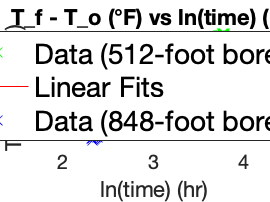


figure(4); %Plot of both the 512 and 848' linear regression data
hold on

plot(fit512,'color','green')
plot(fit848)
title('T_f - T_o (°F) vs ln(time) (hr)')
legend('Data (512-foot borehole)','Linear Fits','','','Data (848-foot borehole)','FontSize',14)
xlabel('ln(time) (hr)')
ylabel('T_f - T_o (°F)')
grid
hold off

#### Q5 Error in the Slope

Syx_512 = fit512.RMSE

Syx_512 = 0.0717

Syx_848 = fit848.RMSE

Syx_848 = 0.0986



sa1d_512 = 0;
for i = 1:numel(t_512)
    new = (log(t_512(i))-mean(log(t_512)))^2;
    sa1d_512 = sa1d_512 + new;
end

Sa1_512 = Syx_512*sqrt(1/sa1d_512)

Sa1_512 = 0.0088


sa1d_848 = 0;
for i = 1:numel(t_848)
    new = (log(t_848(i))-mean(log(t_848)))^2;
    sa1d_848 = sa1d_848 + new;
end

Sa1_848 = Syx_848*sqrt(1/sa1d_848)

Sa1_848 = 0.0121


CI_slope512 = studentst512L * Sa1_512; %95 percent CI for slope of 512 foot bore hole data
CI_slope848 = studentst848L * Sa1_848; %95 percent CI for slope of 848 foot bore hole data
CI_slope512 = CI_slope512(2) %get rid of negative value for later compuation

CI_slope512 = 0.0173

CI_slope848 = CI_slope848(2) %get rid of negative value for later compuation

CI_slope848 = 0.0239

RelAcc_slope512 = (CI_slope512/slope512)*100 %95 CI relative accuracy of slope for 512 foot bore hole data

RelAcc_slope512 = 0.6355

RelAcc_slope848 = (CI_slope848/slope848)*100 %95 CI relative accuracy of slope for 848 foot bore hole data

RelAcc_slope848 = 1.0675

#### Q6 Thermal Conductivity k

k_512 = avgP_512L/(slope512*4*pi) %calculated k from slope value and eqn 1 (512 foot bore hole)

k_512 = 1.8452


k_848 = avgP_848L/(slope848*4*pi) %calculated k from slope value and eqn 1 (848 foot bore hole)

k_848 = 2.0260


%%%error propogation for 512 ft bore hole%%%
%partial derivatives
partial_wrt_slope512 = abs(-avgP_512L/(4*pi*slope512^2))

partial_wrt_slope512 = 0.6796

partial_wrt_q512 = 1/(slope512*4*pi)

partial_wrt_q512 = 0.0293


%uncertainty due to slope (512 foot bore)
u_dt_slope512 = partial_wrt_slope512 * CI_slope512

u_dt_slope512 = 0.0117

%uncertainty due to length normalized heat rate (512 foot bore)
u_dt_q512 = partial_wrt_q512 * CI_avgP512L

u_dt_q512 = 2.5218e-04


%total uncertainty in k for 512 foot bore hole
u_k512 = rssq([u_dt_slope512 u_dt_q512])

u_k512 = 0.0117


%95 percent CI relative accuracy of k for 848 foot bore
RelAcc_k512 = (u_k512/k_512)*100

RelAcc_k512 = 0.6357


%%%error propogation for 848 ft bore hole%%%
%partial derivatives
partial_wrt_slope848 = abs(-avgP_848L/(4*pi*slope848^2))

partial_wrt_slope848 = 0.9063

partial_wrt_q848 = 1/(slope848*4*pi)

partial_wrt_q848 = 0.0356


%uncertainty due to slope (848 foot bore)
u_dt_slope848 = partial_wrt_slope848 * CI_slope848

u_dt_slope848 = 0.0216

%uncertainty due to length normalized heat rate (512 foot bore)
u_dt_q848 = partial_wrt_q848 * CI_avgP848L

u_dt_q848 = 2.6551e-04


%total uncertainty in k for 848 foot bore hole
u_k848 = rssq([u_dt_slope848 u_dt_q848])

u_k848 = 0.0216


%95 percent CI relative accuracy of k for 848 foot bore
RelAcc_k848 = (u_k848/k_848)*100

RelAcc_k848 = 1.0676


both_k = [k_512 k_848]; %put both k values into single array
k_Avg = mean(both_k) %calc avg of both k values

k_Avg = 1.9356

std_both_k = std(both_k) %sample standard deviation of both k values

std_both_k = 0.1279

stdmean_kAvg = std_both_k/sqrt(2) %standard deviation of the mean (k_Avg)

stdmean_kAvg = 0.0904

CI_kAvg = tinv([0.025 0.975],1)*stdmean_kAvg; %95 percent CI for k_Avg
CI_kAvg = CI_kAvg(2) %get rid of negative value

CI_kAvg = 1.1488


%95 percent CI relative accuracy for k_Avg
RelAcc_kAvg = (CI_kAvg/k_Avg)*100

RelAcc_kAvg = 59.3538

#### Q7:  NAU Estimated Borehole Length, L


$$Q=\ \frac{L{\left(T_0 -T_f -T_p \right)}}{R_{tot} }$$
              
$$\textrm{Rtot}=1/k+\textrm{Rb}$$


Rb_512 = 0.210; %resistance of bore from report (512 foot bore hole)
Rb_848 = 0.195; %resistance of bore from report (848 foot bore hole)
Rb = (Rb_512+Rb_848)/2; %average Rb

Rtot_512 = (1/k_512) + Rb_512

Rtot_512 = 0.7520

Rtot_848 = (1/k_848) + Rb_848

Rtot_848 = 0.6886

R_tot = (Rtot_512+Rtot_848)/2

R_tot = 0.7203


Q_nau = 30E6; %Btu/hr

T_in = To_848 - 20;
T_out = T_in + 10;
T_f = (T_in + T_out)/2 %working fluid in reality

T_f = 34.7000

T_p = 6; %holes will be 25 feet apart

L = (Q_nau*R_tot)/(To_848-T_f-T_p)

L = 2.4009e+06


N_bore = ceil(L/850) %number of bore holes needed

N_bore = 2825


unit_cost = 10000; %cost per 850 foot bore hole
cost = N_bore * unit_cost;

fprintf('Total cost of this project is \nestimated to be: $%.2f',cost)

Total cost of this project is 
estimated to be: $28250000.00

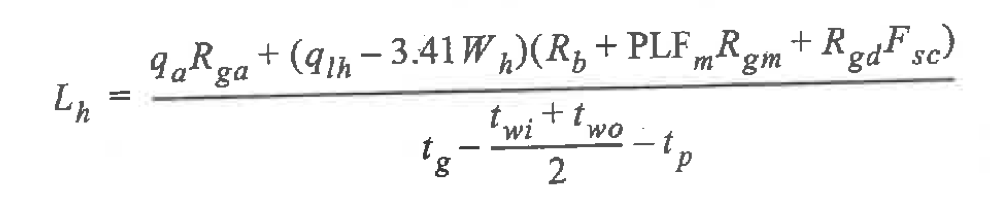

#### Q8: Extra Credit

q_a = 30E6; %Btu/hr
q_lh = 50E6; %Btu/hr
tau_1 = 3650; %days
tau_2 = 3680; %days
tau_f = 3680.25; %days
alpha_g = 1.05; %ft^2/day
d_b = 5.625; %in
d_b = d_b/12; %ft
Fo_f = (4*alpha_g*tau_f)/d_b^2;
Fo_1 = 4*alpha_g*(tau_f-tau_1)/d_b^2;
Fo_2 = 4*alpha_g*(tau_f-tau_2)/d_b^2;
G_f = 0.94; %from Fourier/G-Factor Graph
G_1 = 0.57; %from Fourier/G-Factor Graph
G_2 = 0.24; %from Fourier/G-Factor Graph
R_ga = (G_f-G_1)/k_Avg;
R_gm = (G_1-G_2)/k_Avg;
R_gd = G_2/k_Avg;
F_sc = 1.05;
PLF_m = q_lh/q_a;
W_h = 5.84E6;

L_h = (q_a*R_ga+(q_lh-3.41*W_h)*(Rb_848+PLF_m*R_gm+R_gd*F_sc))/(To_848-T_f-T_p)

L_h = 2.6741e+06


N_h = ceil(L_h/850)

N_h = 3147


cost_h = N_h * 10000

cost_h = 31470000


Land_Area = ((sqrt(N_h)-1)*25)^2 %square feet

Land_Area = 1.8974e+06

Land_Area = Land_Area/2.788E7 %square miles